# 2.12 Lab 3: Rigid Body Tree Introduction

In Matlab, serial robots are represented by rigidBodyTree objects. These objects represent the series of joints and links which make up the arm and can contain both revolute and prismatic joints. To introduce the basics of rigid body trees, you are going to create one for the 2.12 hardware lab robot. Below you can see a diagramatic representation of a rigid body tree, sourced from Mathworks.

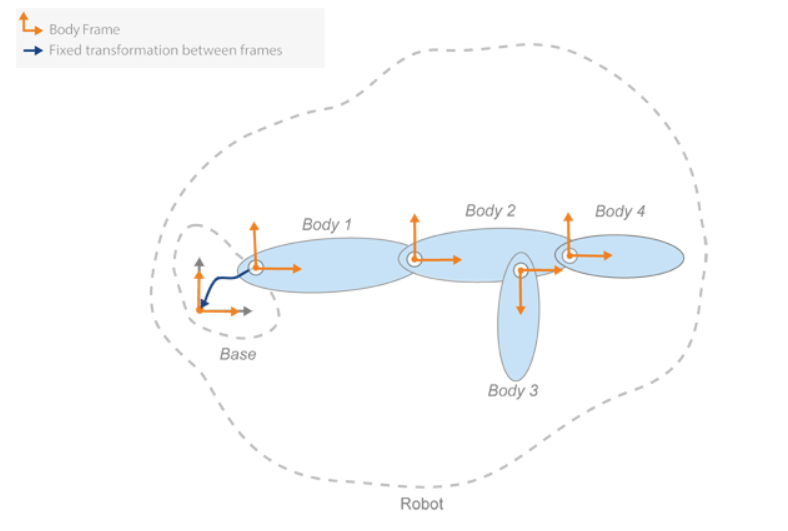

Recall that the 2.12 robot we modeleld in the previous lab was a 2-link, 2-revolute joint robot with the following parameters:

L1 = 0.1524;
L2 = 0.1524;
q1_upper = deg2rad(113.7); % 113.7 degree for 2.12 robot
q1_lower = deg2rad(-113.7); % -113.7 degree for 2.12 robot
q2_upper = deg2rad(161); % 161 degree for 2.12 robot
q2_lower = deg2rad(-161); % -161 degree for 2.12 robot

Using the example here (https://www.mathworks.com/help/robotics/ug/build-a-robot-step-by-step.html) as a reference, create a rigid body tree for the planar, 2-link, 2-revolute-joint 2.12 robot:

% COMPLETE THE BELOW CODE
% Add the first body:
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.PositionLimits = [q1_lower, q1_upper];
jnt1.HomePosition = 0;
tform = trvec2tform([0, 0, 0]); % User defined
setFixedTransform(jnt1,tform);
body1.Joint = jnt1;
robot = rigidBodyTree;
addBody(robot,body1,'base')

% Add the second body:
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.PositionLimits = [q2_lower, q2_upper];
jnt2.HomePosition = 0; % User defined
tform2 = trvec2tform([L1, 0, 0]); % User defined
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;
addBody(robot,body2,'body1'); % Add body2 to body1

% Add the end effector:
bodyEndEffector = rigidBody('endeffector');
tform5 = trvec2tform([L2, 0, 0]); % User defined
setFixedTransform(bodyEndEffector.Joint,tform5);
addBody(robot,bodyEndEffector,'body2');

% Visualize the robot:
config = homeConfiguration(robot)

config = 1×2 struct array with fields:
    JointName
    JointPosition


% MODIFY CODE HERE
%show()
view(2)
%show()
view(2)